function y = sinusoid(t)
    y = sin(2*pi*t) + 0.5*sin(6*pi*t);
end

function y = multisine(t, freqs, amps)
    if nargin < 2
        freqs = [2 5 9];
    end
    if nargin < 3
        amps = [1.0 0.6 0.3];
    end

    y = zeros(size(t));
    for k = 1:length(freqs)
        y = y + amps(k) * sin(2*pi*freqs(k)*t);
    end
end

function y = piecewise_signal(t)
    y = zeros(size(t));
    N = length(t);
    thirds = floor(N/3);

    y(1:thirds) = 1.0;
    y(thirds+1:2*thirds) = -0.5;
    y(2*thirds+1:end) = 0.7;
end

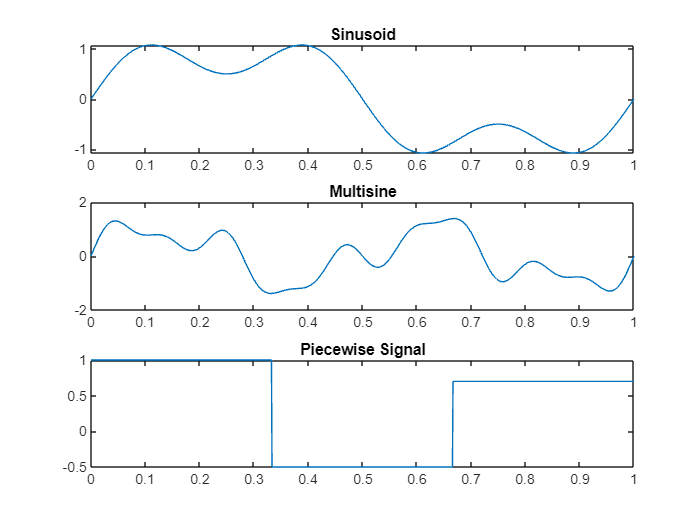

t = linspace(0, 1, 1000);

y1 = sinusoid(t);
y2 = multisine(t);
y3 = piecewise_signal(t);

figure;
subplot(3,1,1); plot(t, y1); title('Sinusoid');
subplot(3,1,2); plot(t, y2); title('Multisine');
subplot(3,1,3); plot(t, y3); title('Piecewise Signal');